# Compression Ratio Calcs

% Geometry
d_i = 44.5/1000; % m
d_a = 66/1000; % m
d_m = (d_i + d_a)/2; % m
beta1 = 88.07831464; % [degrees] 
beta2 = 13.2197262; % [degrees] 

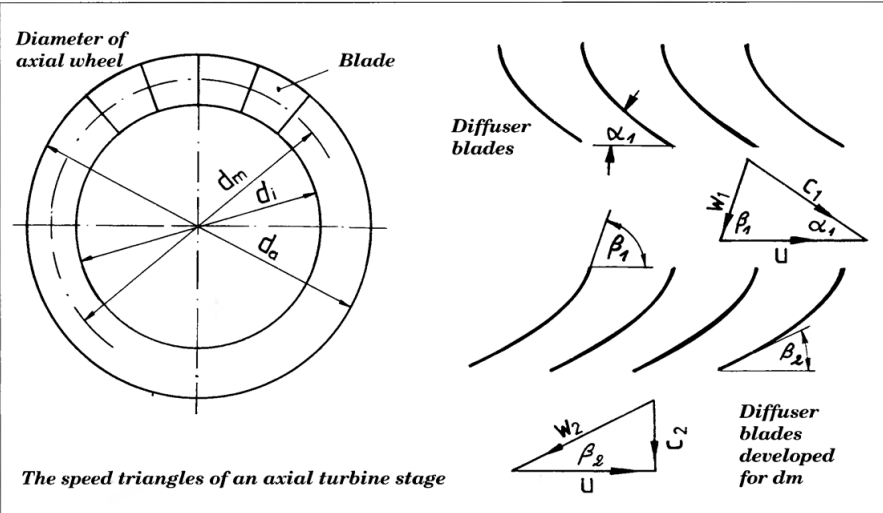

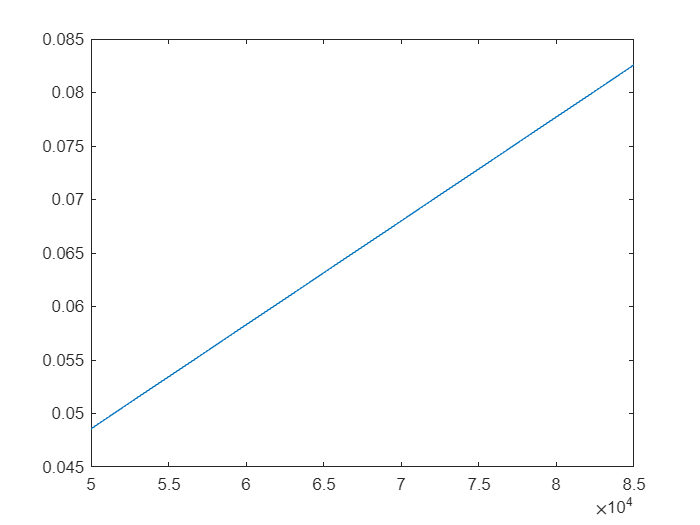

% Properties
RPM =[50000, 55000, 60000, 65000, 70000, 75000, 80000, 85000];
n_max = RPM/60; % % max rotational speed [1/s]
u_max = n_max*(d_a * pi); % max peripheral speed [m/s]
u = d_m * pi * n_max; % mean peripheral speed [m/s]
c2 = u * tand(beta2); % outlet speed [m/s]

gas_T = 873; % max gas temp [K]
rho_N = 1.225; % avg density of air [kg/m^3]
rho = rho_N * (273/gas_T); % density of air given temp [kg/m^3]
outlet_A = (d_a^2 - d_i^2)*pi/2; % Outlet Area [m^2]
m_dot = outlet_A .* c2 * rho; % mass flow rate out of outlet (assumed just air) [kg/s]
F = m_dot .*c2; % estimated thrust [N]

Cp = 1000; % specific heat of air costant pressure [J/kg*K]
T1 = 293; % temperature before inlet [K]
compression_ratio = (((.6.*u.^2)./(Cp*T1))+1).^(1/0.285); % compression ratio of compressor
P_W = (m_dot.*u.^2)./1000; % Shaft power [KWatt]
T3 = (u.^2 .* (1 + (tan(beta2).^2))) ./ (Cp .* .6 .* (1-(1./(1+((.6.*u.^2)./(Cp.*T1)))))); % [K] Temp at tubrine blade


plot(RPM,m_dot)

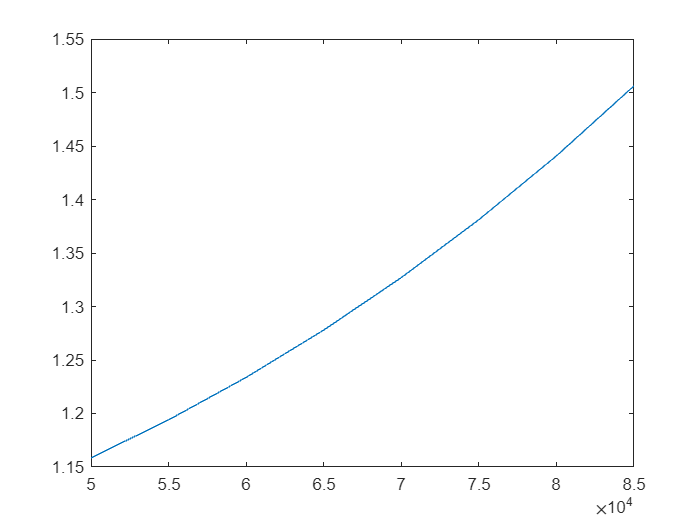

plot(RPM,compression_ratio)

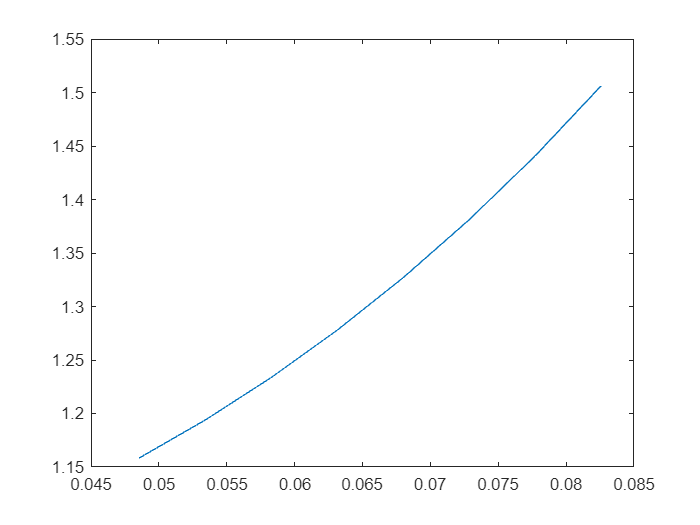

plot(m_dot,compression_ratio)

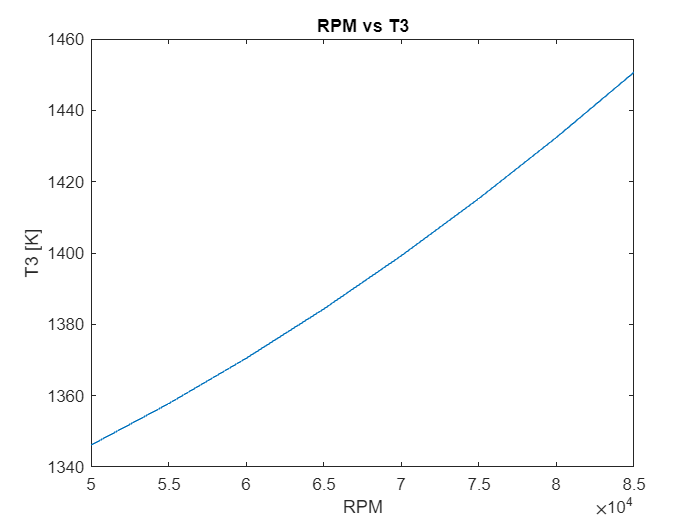

plot(RPM,T3)
title("RPM vs T3")
xlabel("RPM")
ylabel("T3 [K]")

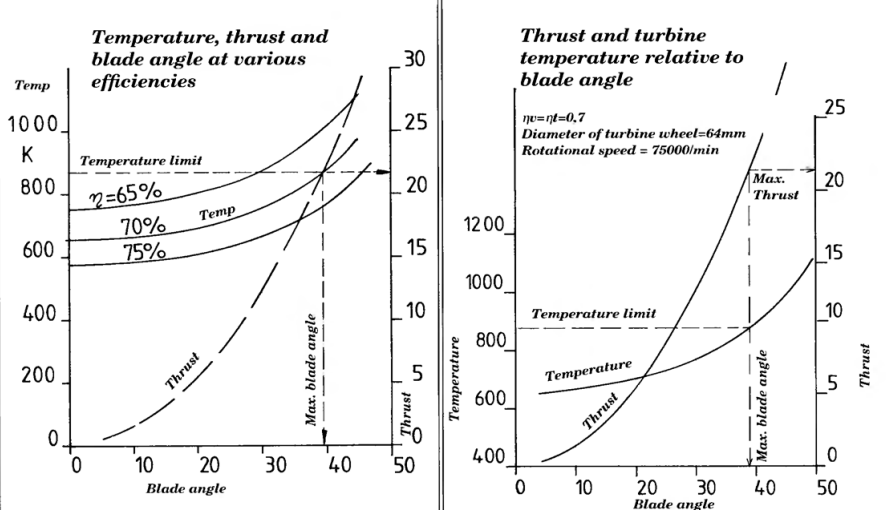

## Combustion chamber

% Geometry
dShaft = 1 / 39.37; % m
dCasing = (4.5-(2*0.065))/39.37; % m
dTurbineHub = 1.751969/ 39.37; % m
m_dotF = m_dot / 16;
% Pattern Factor
PF = .25; 
% Reference area
dRef = dCasing - dShaft;
Aref = (pi/4) *((2*dRef + dShaft)^2+(dShaft)^2);


## Thermo stuff

delta_T = 743 - T1; % [K]
delta_d = .000016 * delta_T * d_a *1000;


## Fuel injection

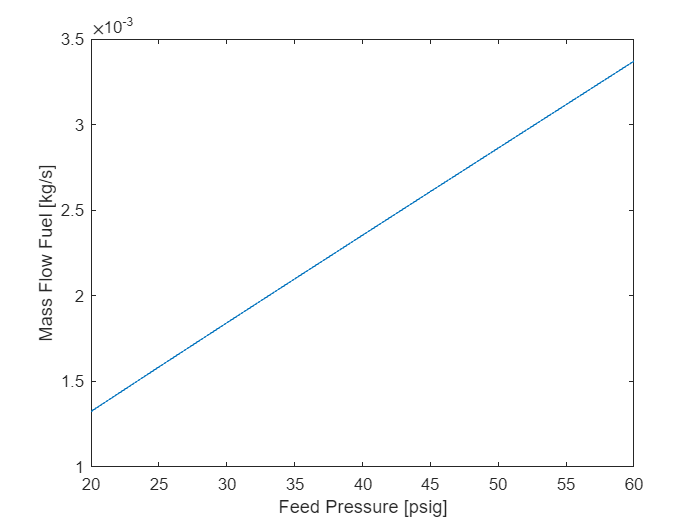

needleD = 0.8192/1000; % meters
numberNeedle = 8;
needleA = numberNeedle*((needleD/2)^2 * pi); % needle area m^2
pressurePsi = [20:5:60]; % feed pressure 
deltaP = 6894.67.* .20 .* pressurePsi;
propaneRho = [4.2325, 4.846, 5.459, 6.073, 6.686, 7.3, 7.913, 8.526, 9.14]; % kg/m^3
Cd = .65;
massFlowF = needleA .* Cd .* sqrt(2.* propaneRho.* deltaP);
plot(pressurePsi,massFlowF)
xlabel("Feed Pressure [psig]")
ylabel("Mass Flow Fuel [kg/s]")
hold on